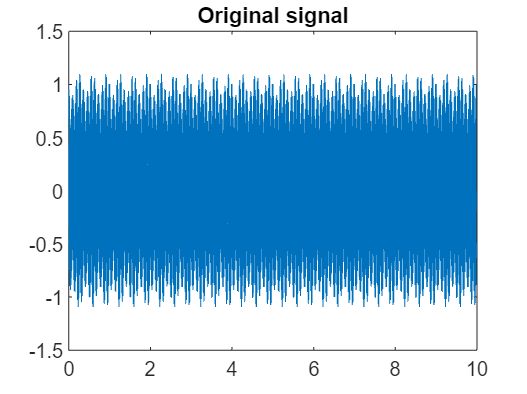

a = 1;
A = 120;
B = 126;
t = 0:(1/200):10 - (1/200);
N = length(t);
x1 = 0.1*sin(A*pi*t) + cos(B*pi*t);
w = hamming(length(x1));
y1 = x1.*transpose(w);
plot(t,x1)
title('Original signal')

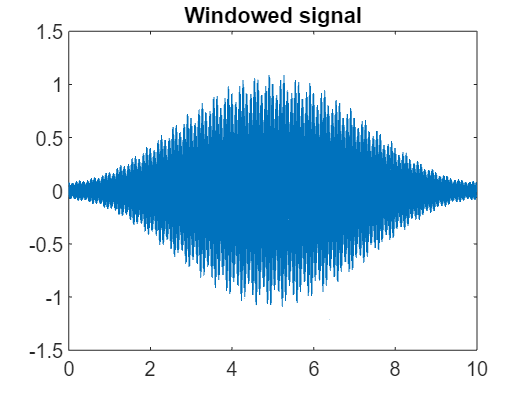

plot(t,y1)
title('Windowed signal')

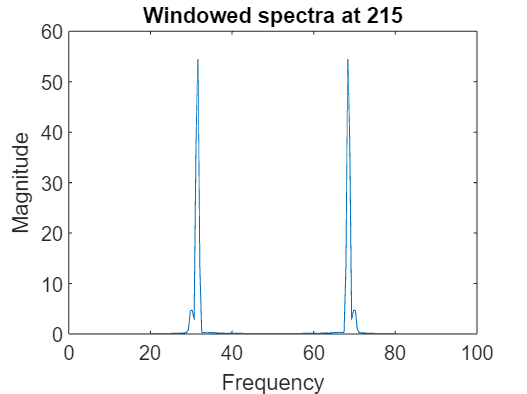




n1 = 215;
w1 = hamming(215);
y1_1 = transpose(w1).*x1(1:215);
f1 = fft(y1_1,n1);
m1 = abs(f1);
freq = (0:length(f1)-1)*100/length(f1);
plot(freq,m1)
title('Windowed spectra at 215')
xlabel('Frequency')
ylabel('Magnitude')

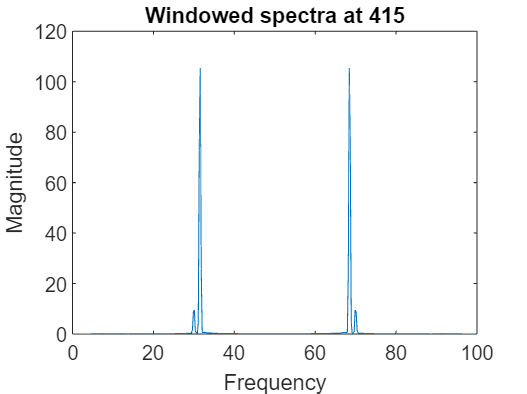


n2 = 415;
w2 = hamming(415);
y1_2 = transpose(w2).*x1(1:415);
f2 = fft(y1_2,n2);
m2 = abs(f2);
freq = (0:length(f2)-1)*100/length(f2);
plot(freq,m2)
title('Windowed spectra at 415')
xlabel('Frequency')
ylabel('Magnitude')

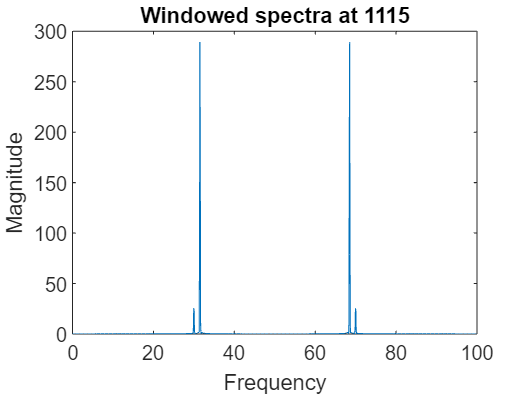


n3 = 1115;
w3 = hamming(1115);
y1_3 = transpose(w3).*x1(1:1115);
f3 = fft(y1_3,n3);
m3 = abs(f3);
freq = (0:length(f3)-1)*100/length(f3);
plot(freq,m3)
title('Windowed spectra at 1115')
xlabel('Frequency')
ylabel('Magnitude')

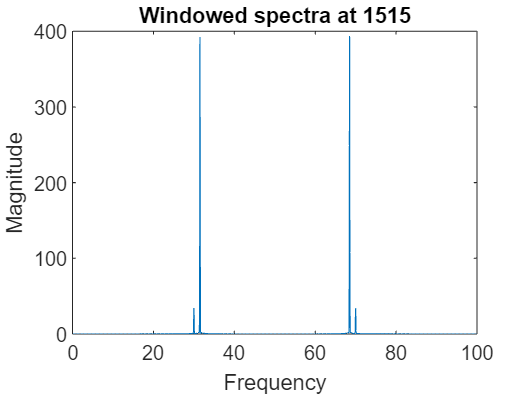


n4 = 1515;
w4 = hamming(1515);
y1_4 = transpose(w4).*x1(1:1515); 
f4 = fft(y1_4,n4);
m4 = abs(f4);
freq = (0:length(f4)-1)*100/length(f4);
plot(freq,m4)
title('Windowed spectra at 1515')
xlabel('Frequency')
ylabel('Magnitude')

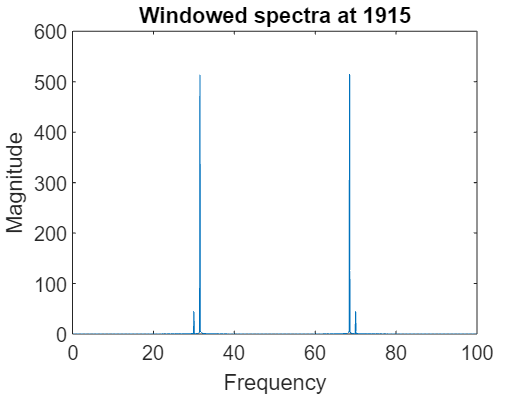


n5 = 1915;
w5 = hamming(1915);
y1_5 = transpose(w5).*x1(1:1915);
f5 = fft(y1,n5);
m5 = abs(f5);
freq = (0:length(f5)-1)*100/length(f5);
plot(freq,m5)
title('Windowed spectra at 1915')
xlabel('Frequency')
ylabel('Magnitude')